# Hodgkin-Huxley simulation

Some code to simulate an axon's response to an applied stimulus current based on the Hodgkin-Huxley equations as described in the 1952 paper (cited below). Allows for visualization of how the gating variables m, h, and n influence ionic currents and membrane voltage, how the gating variables change based on their respective rate constants a and B, and how those rate constants are dependent on the membrane voltage.

Provides code to simulate an action potential using the moden convention (resting potential at -60mV and positive ions into the cell = voltage gets more positive) because that's what we're used to. (PS I know that the resting potential of an axon is around -70mV instead of -60mV but -60mV is consistent with what is shown in "The Annotated Hodgkin and Huxley")

I then replicate the graphs from the Hodgkin-Huxley paper using both the modern convention and the original Hodgkin-Huxley convention (resting potential at 0mV and sign of voltage is flipped)

In "The Annotated Hodgkin and Huxley" (linked below), the modern versions of the graphs should match what is simulated here using the modern convention.

HODGKIN AL, HUXLEY AF. A quantitative description of membrane current and its application to conduction and excitation in nerve. J Physiol. 1952 Aug;117(4):500-44. doi: 10.1113/jphysiol.1952.sp004764. PMID: 12991237; PMCID: PMC1392413.

The Annotated Hodgkin and Huxley: A Reader's Guide https://press.princeton.edu/books/paperback/9780691220635/the-annotated-hodgkin-and-huxley


%% Define constants
clear;

% constants from Table 3 in the paper
Cm = 1.0; % uF/cm^2
g_Na = 120.0; % mS/cm^2
g_K = 36.0; % mS/cm^2
g_l = 0.3; % mS/cm^2

## Define functions for gating variables 

Equilibrium potentials and equations as written in the original Hodgkin-Huxley paper. The constants come from Table 3. In "The Annotated Hodgkin and Huxley", equations for the rate constants are on page 222 and Table 3 is on page 224. 

Note that the modern convention functions and equilibrium potentials differ from the ones in the original paper:

The sign of the voltage has been flipped and the voltage is shifted down by 60mV so the resting potential of the axon is at -60mV instead of 0mV. I would cite my source for the modern convention Nernst potentials but I forgot where I got them from, sorry


% Original HH convention
Vrest_HH = 0; % mV
E_Na_HH = -115; % mV
E_K_HH = 12; % mV
E_l_HH = -10.613; % mV

an_HH = @(v) 0.01*(v+10)/(exp((v+10)/10)-1);
Bn_HH = @(v) 0.125*exp(v/80);
am_HH = @(v) 0.1*(v+25)/(exp((v+25)/10)-1);
Bm_HH = @(v) 4*exp(v/18);
ah_HH = @(v) 0.07*exp(v/20);
Bh_HH = @(v) 1/(exp((v+30)/10)+1);

% Modern convention
Vrest = -60.0; % mV
E_Na = 55.17; % mV
E_K = -72.14; % mV
E_l = -49.24; % mV

an = @(v) 0.01*(-50-v)/(exp((-50-v)/10)-1);
Bn = @(v) 0.125*exp((-60-v)/80);
am = @(v) 0.1*(-35-v)/(exp((-35-v)/10)-1);
Bm = @(v) 4*exp((-60-v)/18);
ah = @(v) 0.07*exp((-60-v)/20);
Bh = @(v) 1/(exp((-30-v)/10)+1);


## Set options for the simulation

Set stimulus current and duration for when we simulate an action potential


Istim = 30; % uA/cm^2
dur = 0.5; % ms
tmax = 10; % ms
dt = 10^-3; % ms
t = 0:dt:tmax; % ms

% Preallocate for speed
stim = zeros(1,length(t)); % uA
Vm = zeros(1,length(t)); % mV
n = zeros(1,length(t));
m = zeros(1,length(t));
h = zeros(1,length(t));
I_Na = zeros(1,length(t)); % uA/cm^2
I_K = zeros(1,length(t)); % uA/cm^2
I_l = zeros(1,length(t)); % uA/cm^2

% Initialize variables
Vm(1) = Vrest; % mV
n(1) = an(Vrest)/(an(Vrest)+Bn(Vrest));
m(1) = am(Vrest)/(am(Vrest)+Bm(Vrest));
h(1) = ah(Vrest)/(ah(Vrest)+Bh(Vrest));


## Simulate the axon's response to a stimulus current (modern convention)


for i = 1:(length(t)-1)
    % Apply stimulus current for specified duration
    if t(i) <= dur
        stim(i) = Istim;
    else
        stim(i) = 0;
    end

    % Compute ionic currents
    I_Na(i) = (g_Na*m(i)^3)*h(i)*(Vm(i)-E_Na);
    I_K(i) = (g_K*n(i)^4)*(Vm(i)-E_K);
    I_l(i) = g_l*(Vm(i)-E_l);

    % Update state variables
    Vm(i+1) = Vm(i) - dt/Cm*(I_Na(i) + I_K(i) + I_l(i) - stim(i));
    n(i+1) = n(i) + dt*(an(Vm(i))*(1-n(i)) - Bn(Vm(i))*n(i));
    m(i+1) = m(i) + dt*(am(Vm(i))*(1-m(i)) - Bm(Vm(i))*m(i));
    h(i+1) = h(i) + dt*(ah(Vm(i))*(1-h(i)) - Bh(Vm(i))*h(i));
end


## Make plots of a simulated action potential

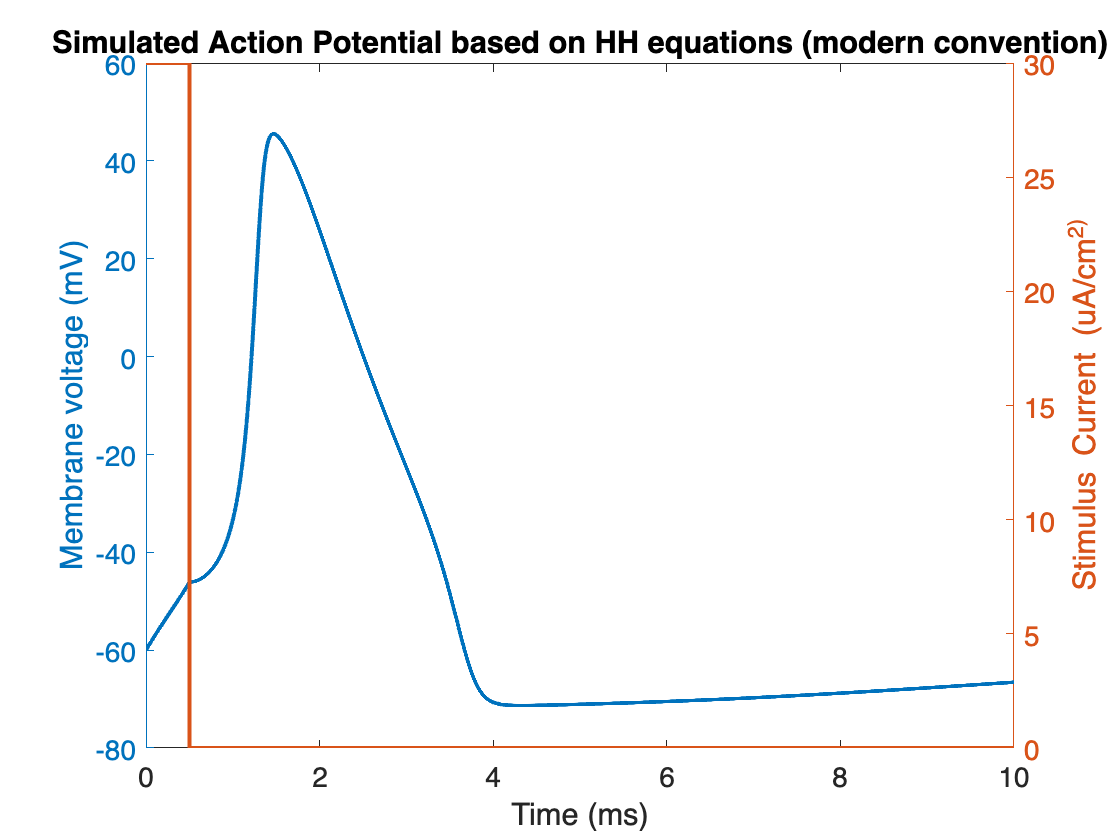


% Plot simulated membrane voltage as a result of the applied stimulus current
figure(1); clf;
yyaxis left;
plot(t, Vm, 'LineWidth', 2);
xlabel('Time (ms)');
ylabel('Membrane voltage (mV)');
yyaxis right;
plot(t, stim, 'LineWidth', 2);
xlabel('Time (ms)');
ylabel('Stimulus Current (uA/cm^2)');
title('Simulated Action Potential based on HH equations (modern convention)')
set(gca, 'FontSize', 14);

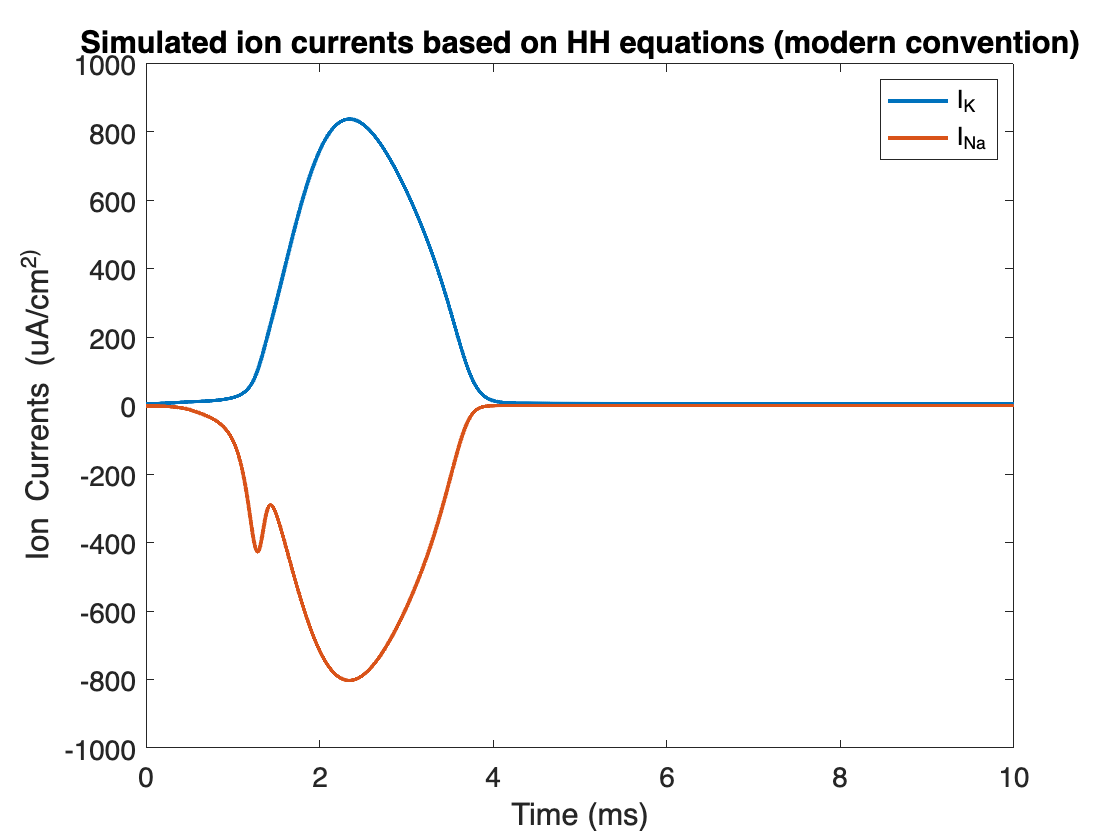


% Plot simulated potassium current (I_K) and sodium current (I_Na)
figure(2); clf;
plot(t, I_K, t, I_Na, 'LineWidth', 2);
xlabel('Time (ms)');
ylabel('Ion Currents (uA/cm^2)');
legend('I_K', 'I_{Na}');
title('Simulated ion currents based on HH equations (modern convention)')
set(gca, 'FontSize', 14);

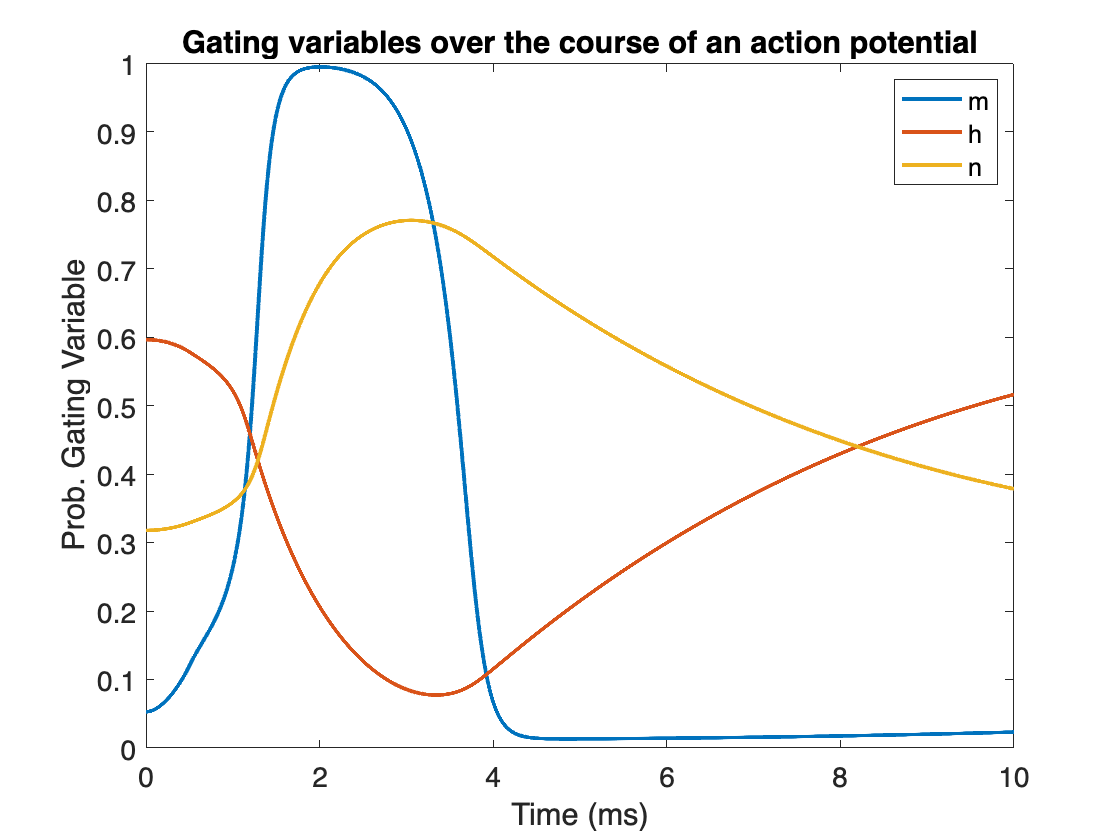


% Plot m, h and n over the course of the action potential
figure(3); clf;
plot(t, m, t, h, t, n, 'LineWidth', 2);
xlabel('Time (ms)');
ylabel('Prob. Gating Variable');
legend('m', 'h', 'n');
title('Gating variables over the course of an action potential')
set(gca, 'FontSize', 14);

## Recreate graphs from the Hodgkin-Huxley paper

Recreate the original graphs from the paper (left subplots) and the corresponding modern versions (right subplots). These should correspond to the graphs shown in "The Annotated Hodgkin and Huxley".


Vm_test = -120.00001:1:60.001;

% Preallocate aaaaalllll the variables for speed
an_modern = zeros(1,length(Vm_test));
Bn_modern = zeros(1,length(Vm_test));
am_modern = zeros(1,length(Vm_test));
Bm_modern = zeros(1,length(Vm_test));
ah_modern = zeros(1,length(Vm_test));
Bh_modern = zeros(1,length(Vm_test));
n_modern = zeros(1,length(Vm_test));
m_modern = zeros(1,length(Vm_test));
h_modern = zeros(1,length(Vm_test));
an_original = zeros(1,length(Vm_test));
Bn_original = zeros(1,length(Vm_test));
am_original = zeros(1,length(Vm_test));
Bm_original = zeros(1,length(Vm_test));
ah_original = zeros(1,length(Vm_test));
Bh_original = zeros(1,length(Vm_test));
n_original = zeros(1,length(Vm_test));
m_original = zeros(1,length(Vm_test));
h_original = zeros(1,length(Vm_test));

% Calculate rate constants a and B for each membrane voltage, 
% and use them to determine m, h, and n at that voltage
for v = 1:numel(Vm_test)
    % original HH version
    an_original(v) = an_HH(Vm_test(v));
    Bn_original(v) = Bn_HH(Vm_test(v));
    am_original(v) = am_HH(Vm_test(v));
    Bm_original(v) = Bm_HH(Vm_test(v));
    ah_original(v) = ah_HH(Vm_test(v));
    Bh_original(v) = Bh_HH(Vm_test(v));
    n_original(v) = an_original(v)/(an_original(v)+Bn_original(v));
    m_original(v) = am_original(v)/(am_original(v)+Bm_original(v));
    h_original(v) = ah_original(v)/(ah_original(v)+Bh_original(v));

    % and also the modern version
    an_modern(v) = an(Vm_test(v));
    Bn_modern(v) = Bn(Vm_test(v));
    am_modern(v) = am(Vm_test(v));
    Bm_modern(v) = Bm(Vm_test(v));
    ah_modern(v) = ah(Vm_test(v));
    Bh_modern(v) = Bh(Vm_test(v));
    n_modern(v) = an_modern(v)/(an_modern(v)+Bn_modern(v));
    m_modern(v) = am_modern(v)/(am_modern(v)+Bm_modern(v));
    h_modern(v) = ah_modern(v)/(ah_modern(v)+Bh_modern(v));
end


## Recreate HH Figure 4 (a_n and B_n as a function of membrane voltage)

Fig 4 is on p. 206-207 of "The Annotated Hodgkin and Huxley"

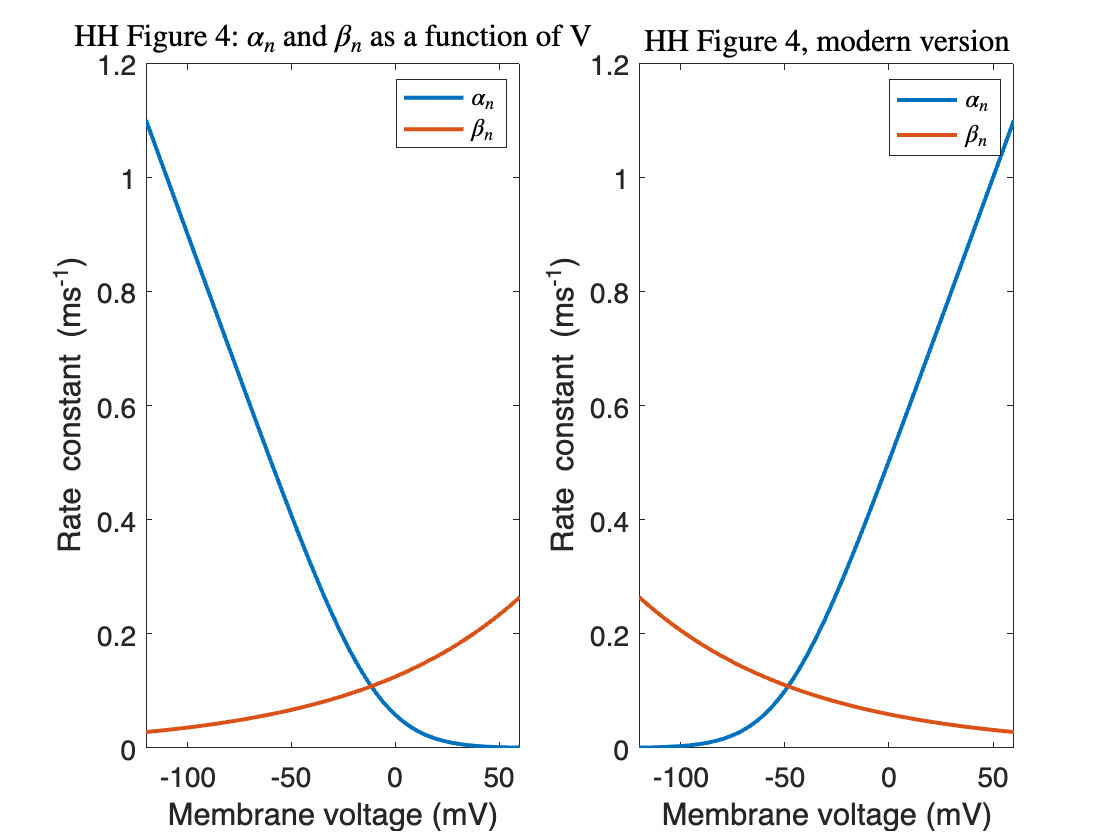


figure(4); clf
% Original HH version
subplot(1,2,1);
plot(Vm_test, an_original, 'DisplayName', '$\alpha_n$', 'LineWidth', 2);
hold on;
plot(Vm_test, Bn_original, 'DisplayName', '$\beta_n$', 'LineWidth', 2);
ylabel('Rate constant (ms^{-1})');
xlabel('Membrane voltage (mV)');
legend('Interpreter', 'latex');
title('HH Figure 4: $\alpha_n$ and $\beta_n$ as a function of V', 'Interpreter', 'latex');
xlim([-120 60]);
set(gca, 'FontSize', 14);
% Modern version
subplot(1,2,2);
plot(Vm_test, an_modern, 'DisplayName', '$\alpha_n$', 'LineWidth', 2);
hold on;
plot(Vm_test, Bn_modern, 'DisplayName', '$\beta_n$', 'LineWidth', 2);
ylabel('Rate constant (ms^{-1})');
xlabel('Membrane voltage (mV)');
legend('Interpreter', 'latex');
title('HH Figure 4, modern version', 'Interpreter', 'latex');
xlim([-120 60]);
set(gca, 'FontSize', 14);

## Recreate HH Figure 5 (n_infinity as a function of membrane voltage)

Fig 5 is on p. 206-207 of "The Annotated Hodgkin and Huxley"

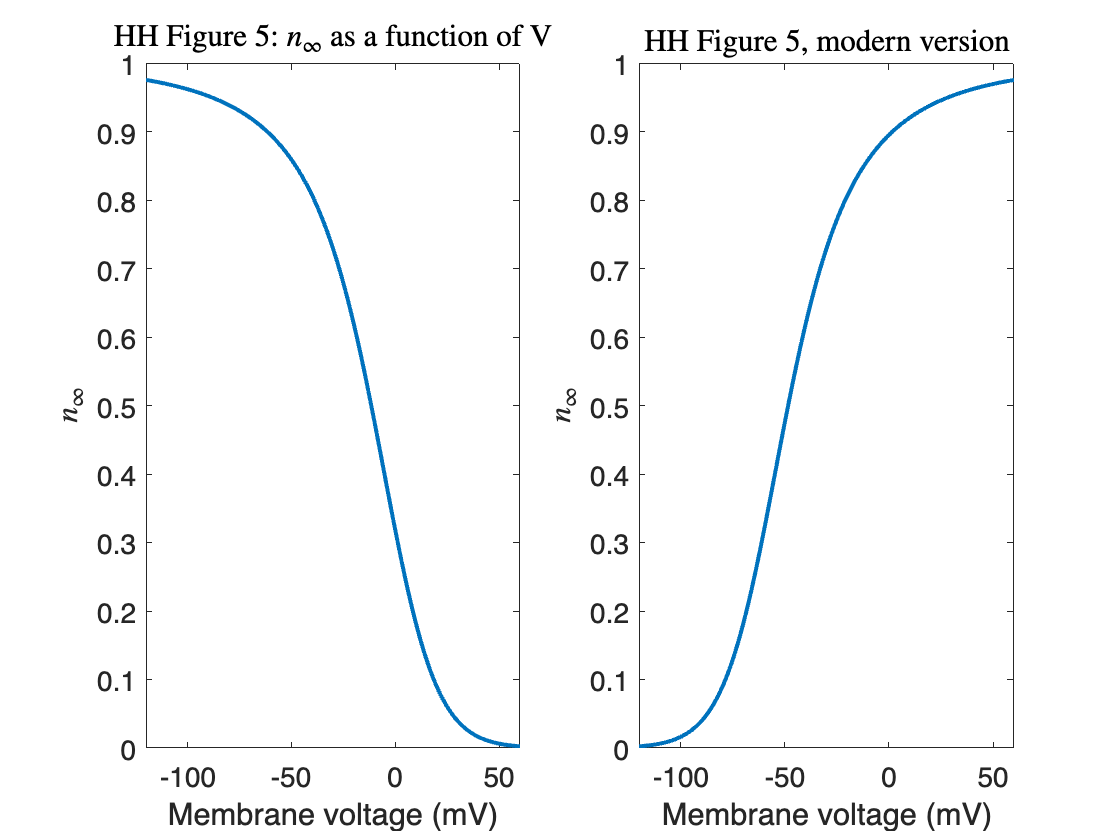


figure(5); clf
% Original HH version
subplot(1,2,1);
plot(Vm_test, n_original, 'LineWidth', 2);
ylabel('$n_{\infty}$', 'Interpreter', 'latex');
xlabel('Membrane voltage (mV)');
title('HH Figure 5: $n_{\infty}$ as a function of V', 'Interpreter', 'latex');
xlim([-120 60]);
set(gca, 'FontSize', 14);
% Modern version
subplot(1,2,2);
plot(Vm_test, n_modern, 'LineWidth', 2);
ylabel('$n_{\infty}$', 'Interpreter', 'latex');
xlabel('Membrane voltage (mV)');
title('HH Figure 5, modern version', 'Interpreter', 'latex');
xlim([-120 60]);
set(gca, 'FontSize', 14);

## Recreate HH Figure 7 (a_m and B_m as a function of membrane voltage)

Fig 7 is on p. 214-215 of "The Annotated Hodgkin and Huxley"

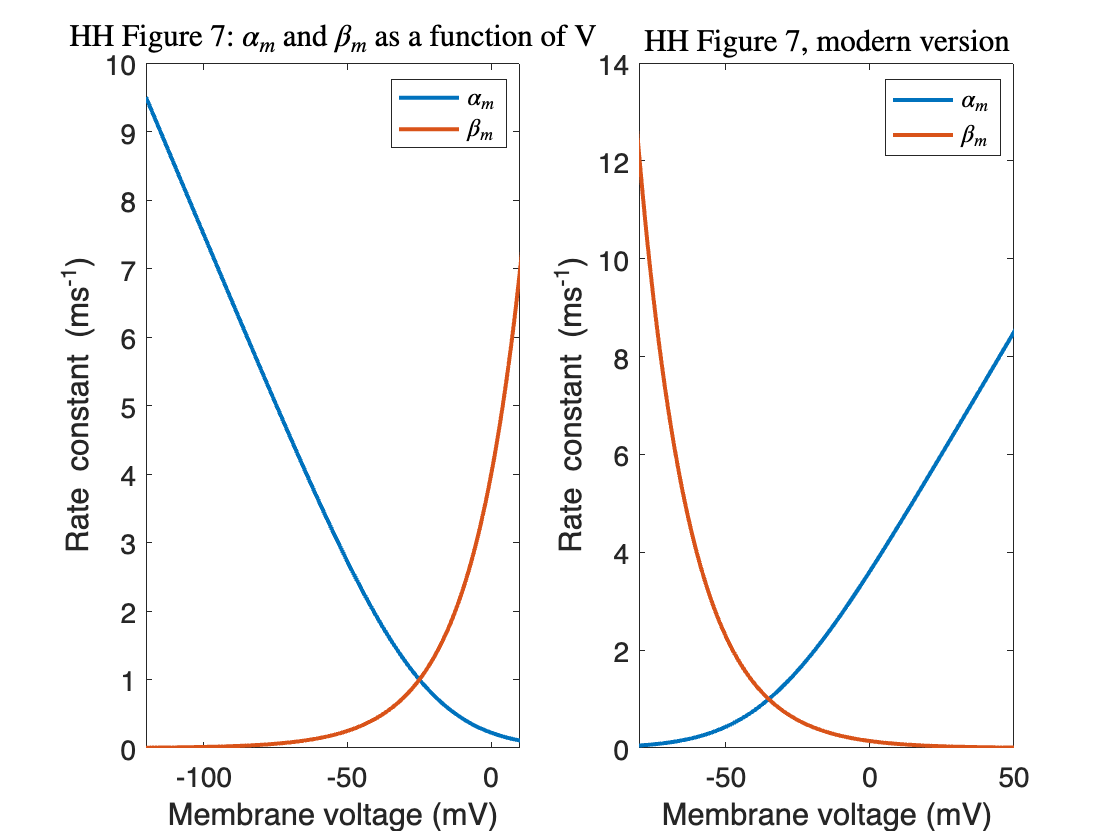


figure(7); clf
% Original HH version
subplot(1,2,1);
plot(Vm_test, am_original, 'DisplayName', '$\alpha_m$', 'LineWidth', 2);
hold on;
plot(Vm_test, Bm_original, 'DisplayName', '$\beta_m$', 'LineWidth', 2);
ylabel('Rate constant (ms^{-1})');
xlabel('Membrane voltage (mV)');
legend('Interpreter', 'latex');
title('HH Figure 7: $\alpha_m$ and $\beta_m$ as a function of V', 'Interpreter', 'latex');
xlim([-120 10]);
set(gca, 'FontSize', 14);
% Modern version
subplot(1,2,2);
plot(Vm_test, am_modern, 'DisplayName', '$\alpha_m$', 'LineWidth', 2);
hold on;
plot(Vm_test, Bm_modern, 'DisplayName', '$\beta_m$', 'LineWidth', 2);
ylabel('Rate constant (ms^{-1})');
xlabel('Membrane voltage (mV)');
legend('Interpreter', 'latex');
title('HH Figure 7, modern version', 'Interpreter', 'latex');
xlim([-80 50]);
set(gca, 'FontSize', 14);

## Recreate HH Figure 8 (m_infinity as a function of membrane voltage)

Fig 8 is on p. 216-217 of "The Annotated Hodgkin and Huxley"

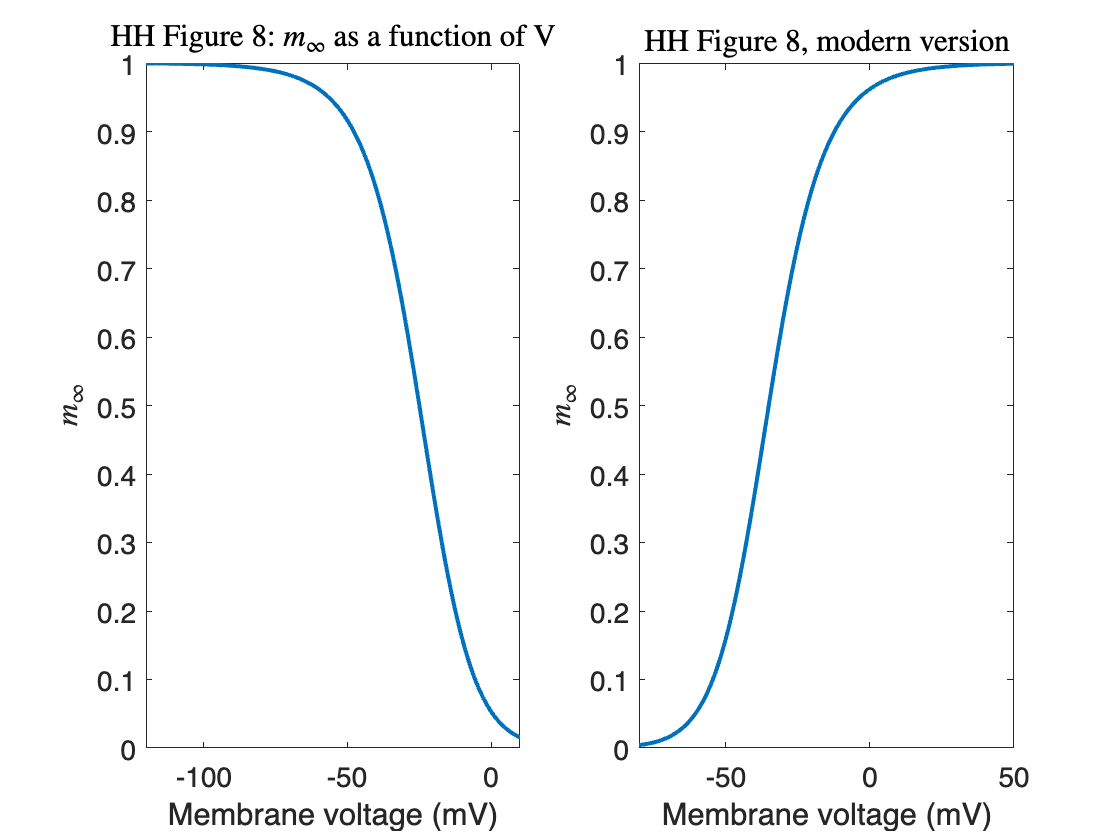


figure(8); clf
% Original HH version
subplot(1,2,1);
plot(Vm_test, m_original, 'LineWidth', 2);
ylabel('$m_{\infty}$', 'Interpreter', 'latex');
xlabel('Membrane voltage (mV)');
title('HH Figure 8: $m_{\infty}$ as a function of V', 'Interpreter', 'latex');
xlim([-120 10]);
set(gca, 'FontSize', 14);
% Modern version
subplot(1,2,2);
plot(Vm_test, m_modern, 'LineWidth', 2);
ylabel('$m_{\infty}$', 'Interpreter', 'latex');
xlabel('Membrane voltage (mV)');
title('HH Figure 8, modern version', 'Interpreter', 'latex');
xlim([-80 50]);
set(gca, 'FontSize', 14);

## Recreate HH Figure 9 (a_h and B_h as a function of membrane voltage)

Fig 9 is on p. 218-219 of "The Annotated Hodgkin and Huxley"

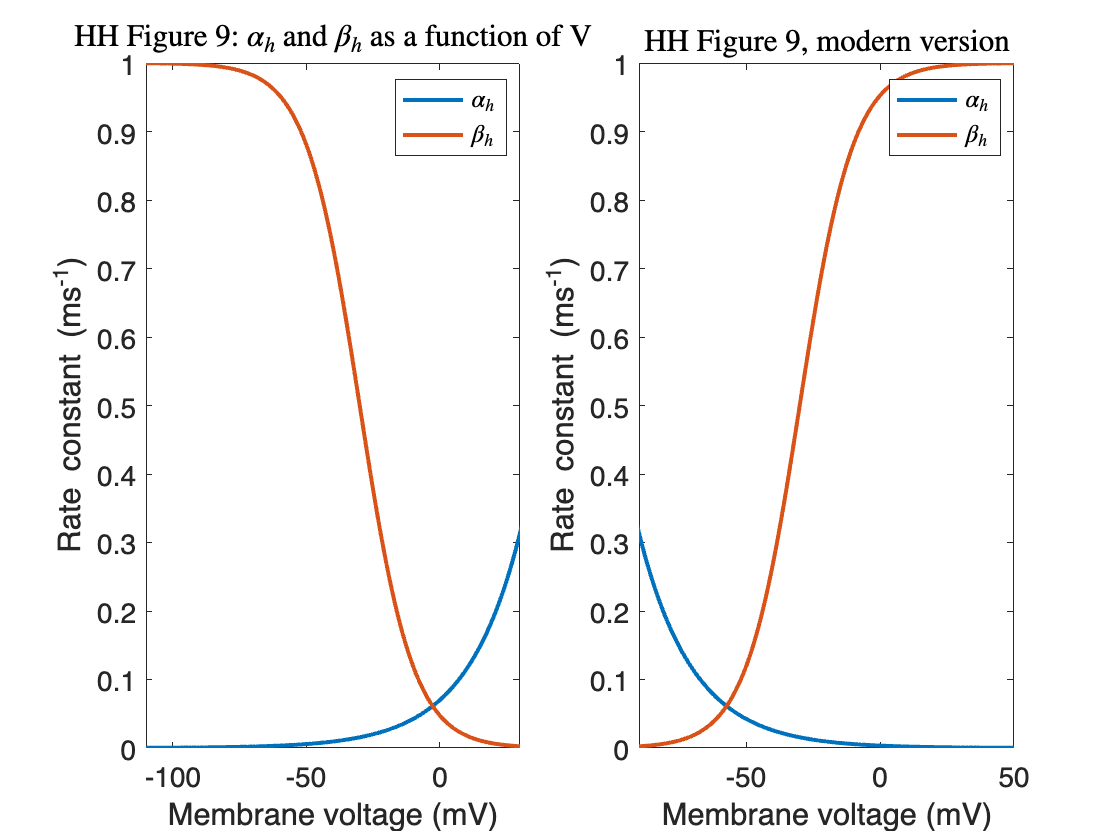


figure(9); clf
% Original HH version
subplot(1,2,1);
plot(Vm_test, ah_original, 'DisplayName', '$\alpha_h$', 'LineWidth', 2);
hold on;
plot(Vm_test, Bh_original, 'DisplayName', '$\beta_h$', 'LineWidth', 2);
ylabel('Rate constant (ms^{-1})');
xlabel('Membrane voltage (mV)');
legend('Interpreter', 'latex');
title('HH Figure 9: $\alpha_h$ and $\beta_h$ as a function of V', 'Interpreter', 'latex');
xlim([-110 30]);
set(gca, 'FontSize', 14);
% Modern version
subplot(1,2,2);
plot(Vm_test, ah_modern, 'DisplayName', '$\alpha_h$', 'LineWidth', 2);
hold on;
plot(Vm_test, Bh_modern, 'DisplayName', '$\beta_h$', 'LineWidth', 2);
ylabel('Rate constant (ms^{-1})');
xlabel('Membrane voltage (mV)');
legend('Interpreter', 'latex');
title('HH Figure 9, modern version', 'Interpreter', 'latex');
xlim([-90 50]);
set(gca, 'FontSize', 14);

## Recreate HH Figure 10 (h_infinity as a function of membrane voltage)

Fig 10 is on p. 220-222 of "The Annotated Hodgkin and Huxley"

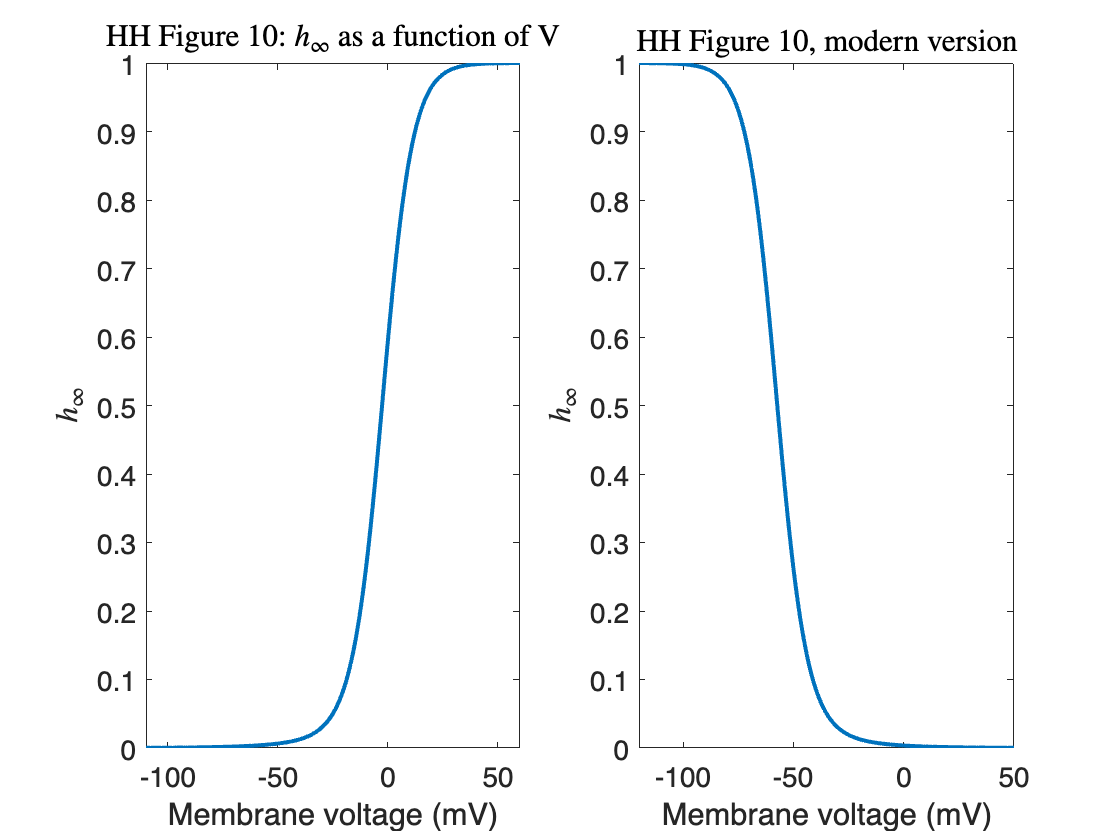


figure(10); clf
% Original HH version
subplot(1,2,1);
plot(Vm_test, h_original, 'LineWidth', 2);
ylabel('$h_{\infty}$', 'Interpreter', 'latex');
xlabel('Membrane voltage (mV)');
title('HH Figure 10: $h_{\infty}$ as a function of V', 'Interpreter', 'latex');
xlim([-110 60]);
set(gca, 'FontSize', 14);
% Modern version
subplot(1,2,2);
plot(Vm_test, h_modern, 'LineWidth', 2);
ylabel('$h_{\infty}$', 'Interpreter', 'latex');
xlabel('Membrane voltage (mV)');
title('HH Figure 10, modern version', 'Interpreter', 'latex');
xlim([-120 50]);
set(gca, 'FontSize', 14);